clear all;
close all;
clc;

## Generating sample data.

The sx and sy arrays store the location of sensors. 

The ex and ey arrays store the locations of the exictation events.

For now, let's just assign some arbitrary predetermined locations. In the field, these could be assessed manually or via other methods like self configuration achieved through something like ${\mathrm{SCSV}}^2$.

sx = [1 4];
sy = [1 5];

ex = [1.5, 4];
ey = [3.5, 2.5];

**Sensors **are blue. 

    This means the first sensor, $s_1$, is located at $\left(1,1\right)$. 

    The second sensor, $s_2$, is located at the point $\left(4,5\right)$. 

**Excitations** are orange.

    The location of the first excitation, $e_1$, is at $\left(1\ldotp 5,3\ldotp 5\right)$.

    The location of the second excitation, $e_2$ is at $\left(4,2\ldotp 5\right)$.

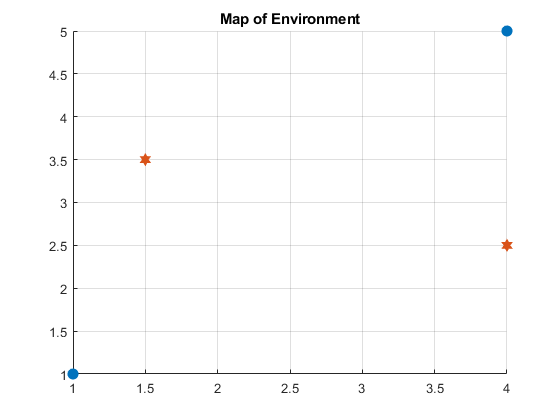

hold off;

scatter(sx, sy, 70, 'filled'); % Location of sensors
grid on
title("Map of Environment");

hold on;
scatter(ex, ey, 100, 'filled', 'hexagram'); % Location of excitation

hold off;

Next, we need some sensor data. The **Mexican hat wavelet** is chosen as the mother wavelet as it is a good representation of the footstep-induced vibration signals due to its similarity in shape. 

There's a few methods that MATLAB provides for generating a Mexican hat wavelet, but the one I chose was the '*wavefun*' command, which outputs a $\psi$ and an xval. 

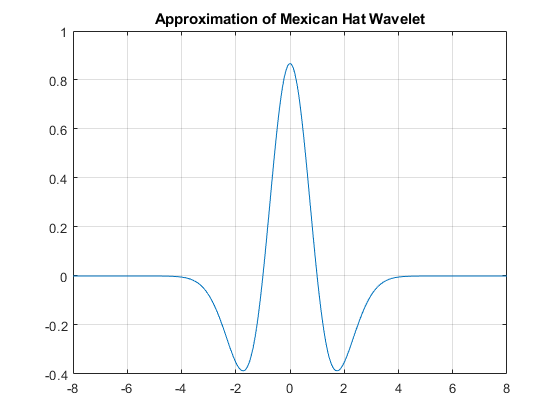

% See https://www.mathworks.com/help/wavelet/ref/waveinfo.html 
% and also https://www.mathworks.com/help/wavelet/ref/wavefun.html

[psi,xval] = wavefun('mexh',9);
plot(xval,psi)
grid on
title(['Approximation of Mexican Hat Wavelet'])


% See also https://www.mathworks.com/help/wavelet/ref/mexihat.html

That aforementioned $\psi$ can be given Gaussian noise via the '*awgn*' function provided by MATLAB.

The acronym '*awgn*' stands for "**Add white Gaussian noise**".

%[psi,xval] = wavefun('mexh',9);
noisy_psi = awgn(psi,10,'measured');

'awgn' requires Communications Toolbox.

plot(xval,noisy_psi)
grid on
title(['Noisy Mexican Hat Wavelet'])